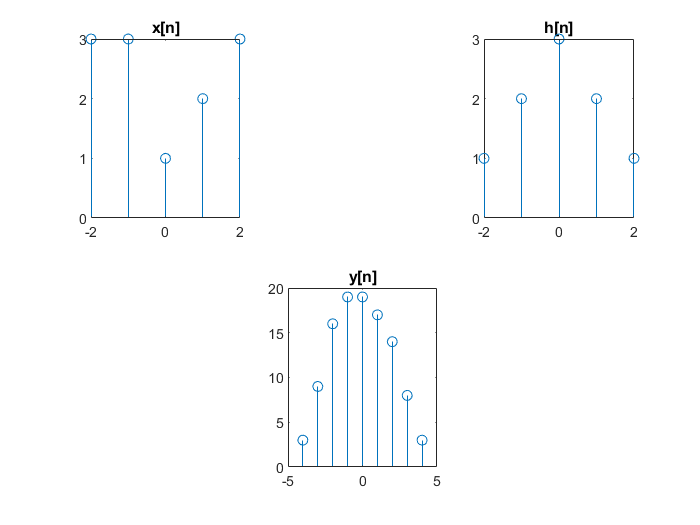

clc 
clear 
close all

o=2;p=-o:1:o;
x=zeros(size(p));
x(p==-2)=3;x(p==-1)=3;x(p==0)=1;x(p==1)=2;x(p==2)=3;
subplot(2,3,1);stem(p,x);title('x[n]');
h=zeros(size(p));
h(p==-2)=1;h(p==-1)=2;h(p==0)=3;h(p==1)=2;h(p==2)=1;
subplot(2,3,3);stem(p,h);title('h[n]');
y=conv(x,h);
p=-4:1:4;
subplot(2,3,5);stem(p,y);title('y[n]');